## Balken mit Finite-Differenzen-Methode simulieren

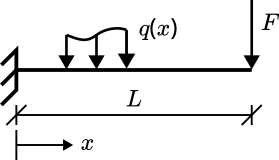

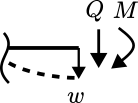

Grundgleichungen:

DGL für Biegelinie gesamt: $(EI(x)w''(x))'' = q(x)$

Teilschritte:

Querkraft $\frac{dQ(x)}{dx} = -q(x)$

Moment $\frac{dM(x)}{dx} = Q(x)$

Biegeline $\frac{d^2w(x)}{dx^2} EI(x) = -M(x)$

Randbedingungen: 


$$Q(x = L) = F, \;\; M(x=L) = 0, \;\; w'(x=0) = 0, \;\; w(x = 0) = 0$$


Eingabeparameter:

clearvars;

N = 11;             % number of points
L = 1;              % [m] length of cantilever
q = 0;              % [N/m] line load
F = 1;              % [N] load at tip of cantilever
E = 1e5;            % [N/m2] Youngs modulus

delta_x = L/(N-1);
x_axis = 0:delta_x:L;

b = 0.1;            % [m] beam width
h = 0.1*ones(1,N);  % [m] beam height vector
%h(7) = 0.05;
%h = 0.15-x_axis*0.1;

I = b*h.^3/12;   % moment of inertia

disp(h)

    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000



FDM - Diskretisierung

### Querkraft


$$\frac{dQ(x)}{dx} = -q(x)$$


Approximation mit Vorwärtsdifferenz: 


$$\frac{Q_{i+1} - Q_i}{\Delta x} = -q_i \;\; \Leftrightarrow \;\;  - Q_i + Q_{i+1} = -q_i \Delta x$$


Gleichungssystem aufstellen: VDS Schema

forward_coefs = zeros(N-1,N);
for i=1:N-1
    forward_coefs(i,i) = -1;
    forward_coefs(i,i+1) = 1;
end
disp(forward_coefs)

    -1     1     0     0     0     0     0     0     0     0     0
     0    -1     1     0     0     0     0     0     0     0     0
     0     0    -1     1     0     0     0     0     0     0     0
     0     0     0    -1     1     0     0     0     0     0     0
     0     0     0     0    -1     1     0     0     0     0     0
     0     0     0     0     0    -1     1     0     0     0     0
     0     0     0     0     0     0    -1     1     0     0     0
     0     0     0     0     0     0     0    -1     1     0     0
     0     0     0     0     0     0     0     0    -1     1     0
     0     0     0     0     0     0     0     0     0    -1     1



Analogie zum Expliziten Euler-Verfahren:


$$Q_{i+1} = Q_i - q_i  \Delta x$$


(Würde "Anfangsbedingung" für $Q_1$benötigen)

Hier: Randbedingung am rechten Rand


$$Q(x=L) = Q_N = -F$$


% coefficient matrix
Q_coefs = zeros(N,N);
Q_coefs(1:N-1,1:N) = forward_coefs;
Q_coefs(N,N) = 1; % BC: Q(x=L)
disp(Q_coefs)

    -1     1     0     0     0     0     0     0     0     0     0
     0    -1     1     0     0     0     0     0     0     0     0
     0     0    -1     1     0     0     0     0     0     0     0
     0     0     0    -1     1     0     0     0     0     0     0
     0     0     0     0    -1     1     0     0     0     0     0
     0     0     0     0     0    -1     1     0     0     0     0
     0     0     0     0     0     0    -1     1     0     0     0
     0     0     0     0     0     0     0    -1     1     0     0
     0     0     0     0     0     0     0     0    -1     1     0
     0     0     0     0     0     0     0     0     0    -1     1
     0     0     0     0     0     0     0     0     0     0     1



% vector
Q_vector = zeros(N,1);
for i=1:N-1
    Q_vector(i) = -q*delta_x;
end
Q_vector(N) = F; % BC: Q(x=L) = F
disp(Q_vector)

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1



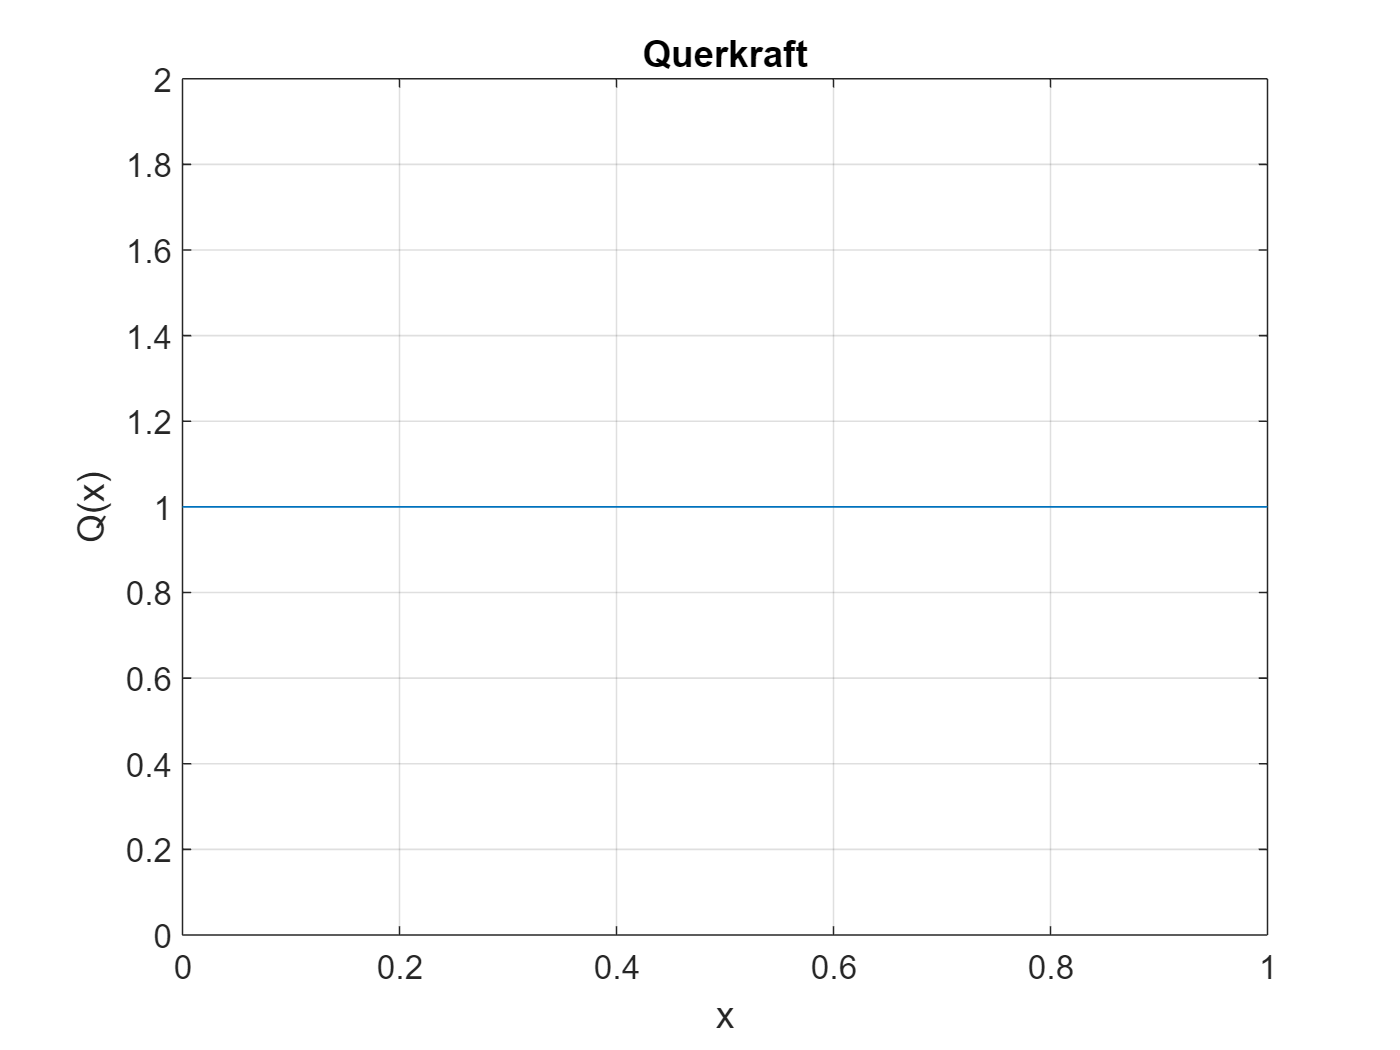

% solve
Q = Q_coefs\Q_vector;

plot(x_axis,Q)
title('Querkraft')
ylabel('Q(x)')
xlabel('x')
grid on

### Biegemoment


$$\frac{dM(x)}{dx} = Q(x)$$


Approximation mit Zentraldifferenz: 


$$\frac{M_{i+1} - M_{i-1}}{2\Delta x} = Q_i$$


% central difference
central_coefs = zeros(N-2,N);
for i=1:N-2
    central_coefs(i,i) = -1/2;
    central_coefs(i,i+1) = 0;
    central_coefs(i,i+2) = 1/2;
end
disp(central_coefs)

   -0.5000         0    0.5000         0         0         0         0         0         0         0         0
         0   -0.5000         0    0.5000         0         0         0         0         0         0         0
         0         0   -0.5000         0    0.5000         0         0         0         0         0         0
         0         0         0   -0.5000         0    0.5000         0         0         0         0         0
         0         0         0         0   -0.5000         0    0.5000         0         0         0         0
         0         0         0         0         0   -0.5000         0    0.5000         0         0         0
         0         0         0         0         0         0   -0.5000         0    0.5000         0         0
         0         0         0         0         0         0         0   -0.5000         0    0.5000         0
         0         0         0         0         0         0         0         0   -0.5000         0    0.5000



Randbedingung


$$M(x=L) = M_N = 0$$


Rückwärtsdifferenz am rechten Rand


$$\frac{M_N-M_{N-1}}{\Delta x} = Q_N$$



% coefficient matrix
M_coefs = zeros(N,N);
M_coefs(1:N-2,1:N) = central_coefs;
M_coefs(N-1,N-1:N) = [-1,1]; % 2-point backward
M_coefs(N,N) = 1; % BC: M(x=L)
disp(M_coefs)

   -0.5000         0    0.5000         0         0         0         0         0         0         0         0
         0   -0.5000         0    0.5000         0         0         0         0         0         0         0
         0         0   -0.5000         0    0.5000         0         0         0         0         0         0
         0         0         0   -0.5000         0    0.5000         0         0         0         0         0
         0         0         0         0   -0.5000         0    0.5000         0         0         0         0
         0         0         0         0         0   -0.5000         0    0.5000         0         0         0
         0         0         0         0         0         0   -0.5000         0    0.5000         0         0
         0         0         0         0         0         0         0   -0.5000         0    0.5000         0
         0         0         0         0         0         0         0         0   -0.5000         0    0.5000
 

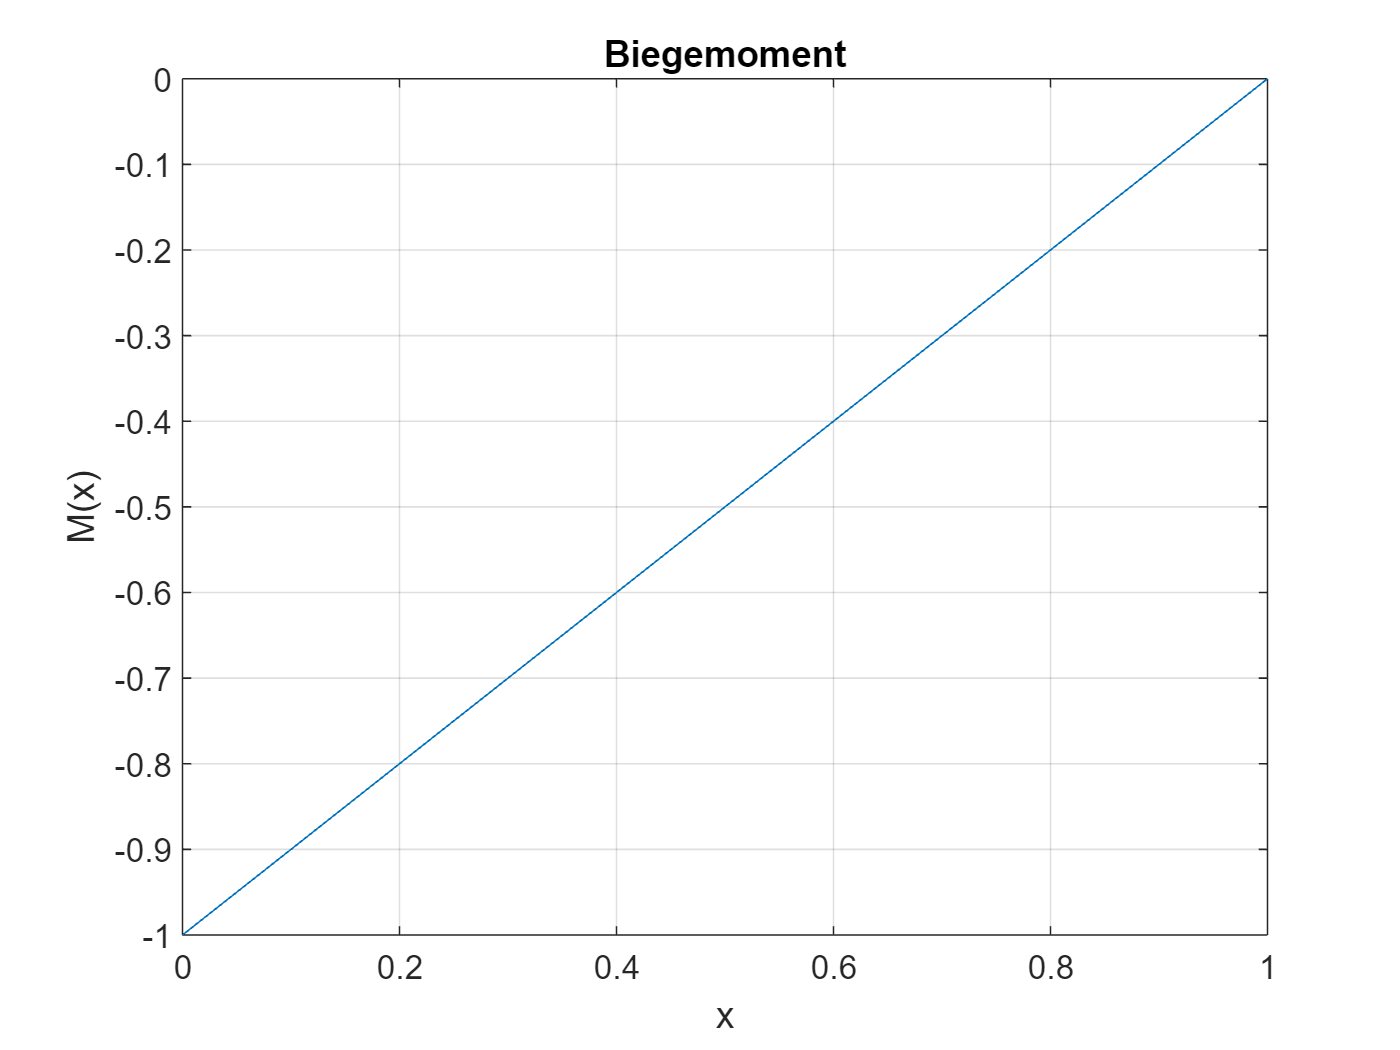


% vector
M_vector = zeros(N,1);
for i=1:N-1
    M_vector(i) = Q(i)*delta_x;
end
M_vector(N) = 0; % BC: M(x=L) = 0

% solve
M = M_coefs\M_vector;

plot(x_axis,M)
title('Biegemoment')
ylabel('M(x)')
xlabel('x')
grid on

### Biegelinie


$$\frac{d^2w(x)}{dx^2} EI(x) = -M(x)$$


approximiert mit Differenzenquotient für zweite Ableitung:


$$\frac{w_{i-1} - 2w_i + w_{i+1}}{(\Delta x^2)} EI(x) = -M(x)$$


second_derivative_coefs = zeros(N-2,N);
for i = 1:N-2
    second_derivative_coefs(i,i) = 1;
    second_derivative_coefs(i,i+1) = -2;
    second_derivative_coefs(i,i+2) = 1;
end
disp(second_derivative_coefs)

     1    -2     1     0     0     0     0     0     0     0     0
     0     1    -2     1     0     0     0     0     0     0     0
     0     0     1    -2     1     0     0     0     0     0     0
     0     0     0     1    -2     1     0     0     0     0     0
     0     0     0     0     1    -2     1     0     0     0     0
     0     0     0     0     0     1    -2     1     0     0     0
     0     0     0     0     0     0     1    -2     1     0     0
     0     0     0     0     0     0     0     1    -2     1     0
     0     0     0     0     0     0     0     0     1    -2     1



Randbedingungen:


$$w_1 = 0$$


$\frac{dw_1}{dx} \approx \frac{- 3w_1+4w_2 - w_3}{2\Delta x} = 0$      3-Punkt-Vorwärtsdifferenz (Konvergenzordnung 2)

w_vector = zeros(N,1);
for i=3:N 
    w_vector(i) = -M(i-1)/(E*I(i-1)); % without delta_x
end
w_vector(1) = 0; % BC: w(x=0) = 0
w_vector(2) = 0; % BC: w'(x=0) = 0
disp(w_vector)

         0
         0
    1.0800
    0.9600
    0.8400
    0.7200
    0.6000
    0.4800
    0.3600
    0.2400
    0.1200




% coefficient matrix
w_coefs = zeros(N,N);
w_coefs(3:N,1:N) = second_derivative_coefs/(delta_x^2);
w_coefs(1,1) = 1; % BC w(x=0)
w_coefs(2,1:3) = [-3, 4, -1]/(2*delta_x); % BC: w'(x=0) -> 2nd order forward difference
disp(w_coefs)

    1.0000         0         0         0         0         0         0         0         0         0         0
  -15.0000   20.0000   -5.0000         0         0         0         0         0         0         0         0
  100.0000 -200.0000  100.0000         0         0         0         0         0         0         0         0
         0  100.0000 -200.0000  100.0000         0         0         0         0         0         0         0
         0         0  100.0000 -200.0000  100.0000         0         0         0         0         0         0
         0         0         0  100.0000 -200.0000  100.0000         0         0         0         0         0
         0         0         0         0  100.0000 -200.0000  100.0000         0         0         0         0
         0         0         0         0         0  100.0000 -200.0000  100.0000         0         0         0
         0         0         0         0         0         0  100.0000 -200.0000  100.0000         0         0
 

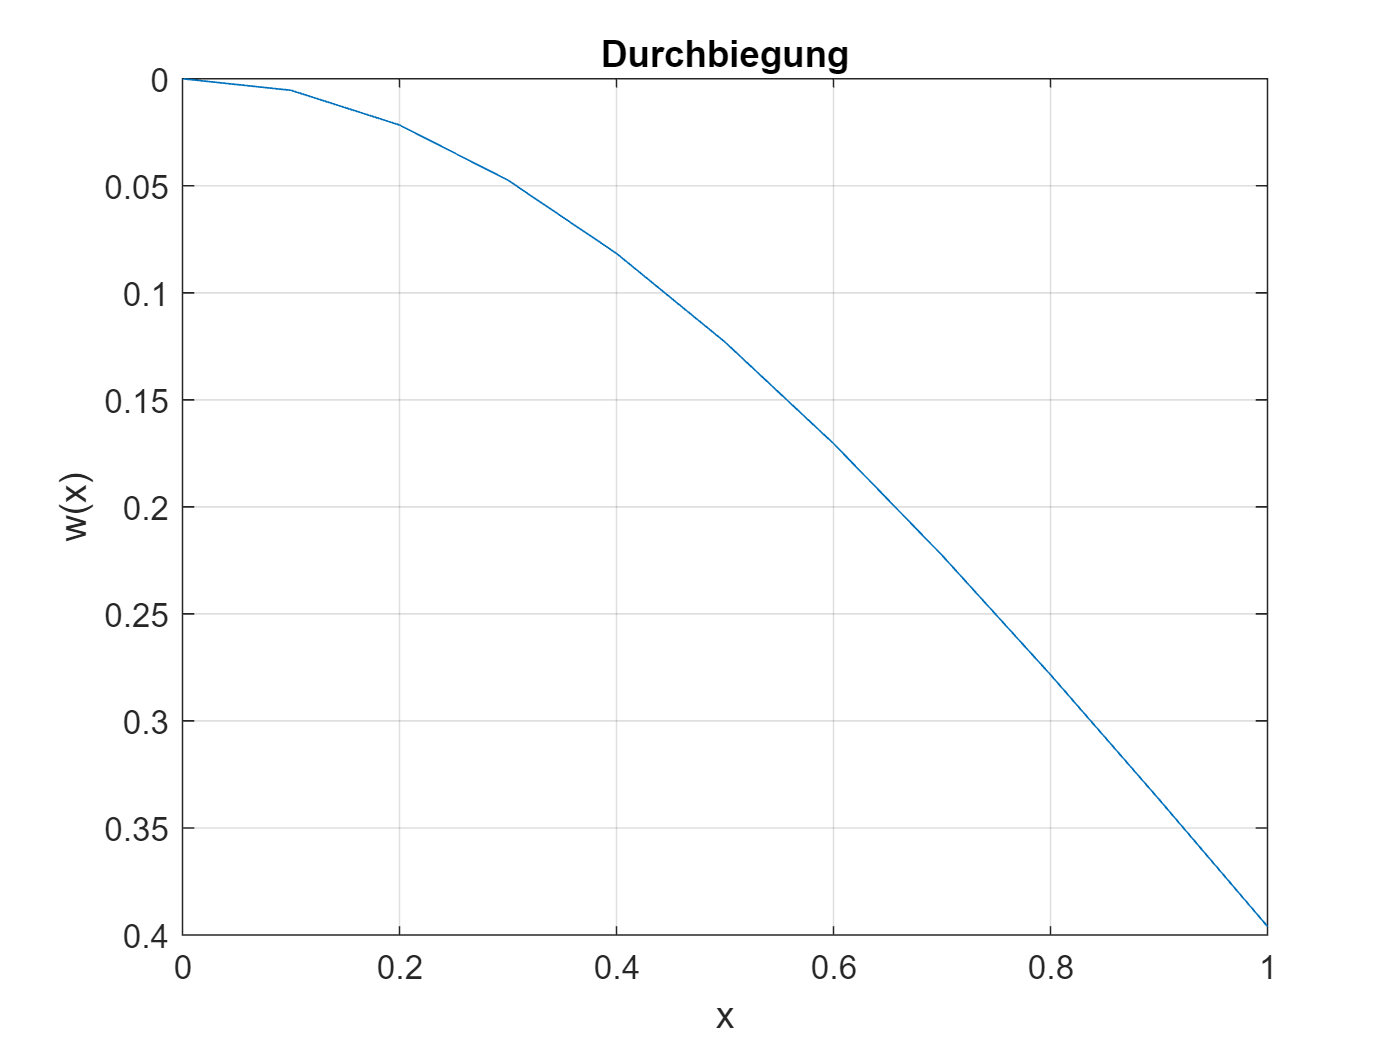


% solve
w = w_coefs\w_vector;

plot(x_axis,w)
set(gca, 'YDir','reverse')
title('Durchbiegung')
ylabel('w(x)')
xlabel('x')
grid on

Analytische Lösung


$$w(x) = \frac{1}{EI}\Bigl(\frac{FLx^2}{2} - \frac{Fx^3}{6}\Bigr)$$



$$w(x= L) = \frac{FL^3}{3EI}$$


%% analytical solution:
% for constant EI, q(x) = 0 !
I_const = b*h(6)^3/12;
w_analytical = @(x) (F*L*x.^2/2 - F*x.^3/6)/(E*I_const);

w_max_FDM = max(w)

w_max_FDM = 0.3960

w_max_analyt = F*L/(3*E*I_const)

w_max_analyt = 0.4000

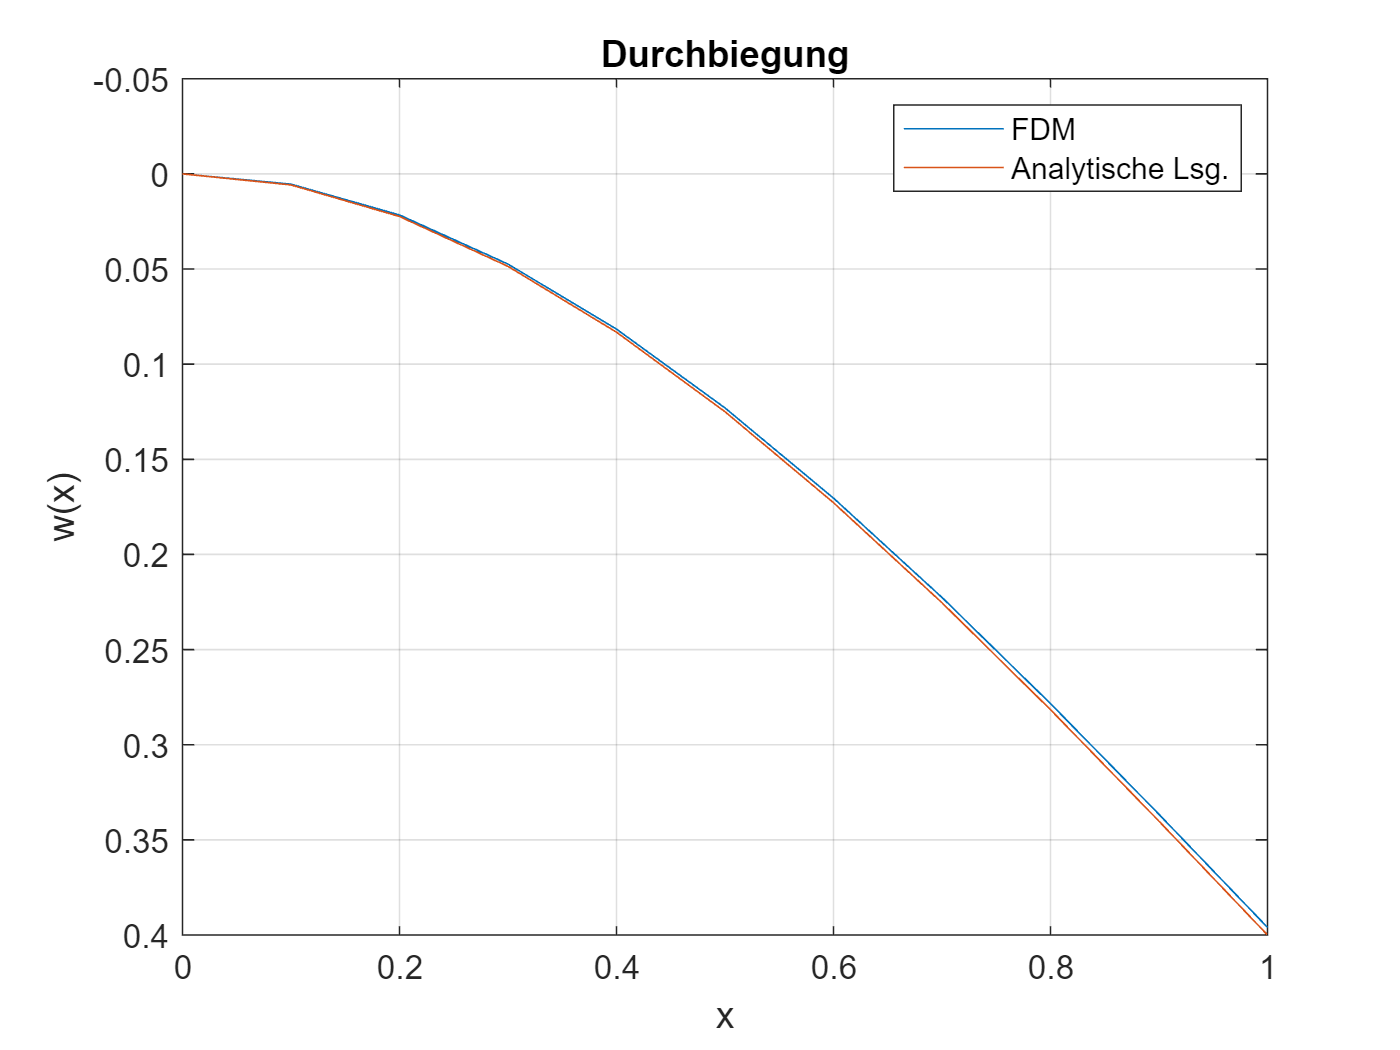


plot(x_axis,w,'DisplayName','FDM')
hold on
plot(x_axis,w_analytical(x_axis),'DisplayName','Analytische Lsg.')
hold off
set(gca, 'YDir','reverse')
title('Durchbiegung')
ylabel('w(x)')
xlabel('x')
grid on
legend